% PI controller
t1 = 0.01

t1 = 0.0100

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Ki = 10;
Kp = 0.5;
Ki1 = 10;
Kp1= .9;



C_s = Kp * ((s + (Ki/Kp))/s)

C_s =
 
  0.5 s + 10
  ----------
      s
 
Continuous-time transfer function.



C_s1 = Kp1 * ((s + (Ki1/Kp1))/s)

C_s1 =
 
  0.9 s + 10
  ----------
      s
 
Continuous-time transfer function.



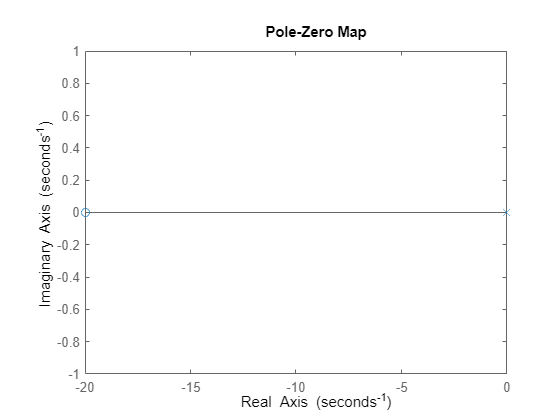

%C_s = (s+1)/(s+10)
figure;
pzmap(C_s)

%rlocus(C_s)
G_0_s = G_w_small

G_0_s =
 
  171.3
  ------
  s + 11
 
Continuous-time transfer function.



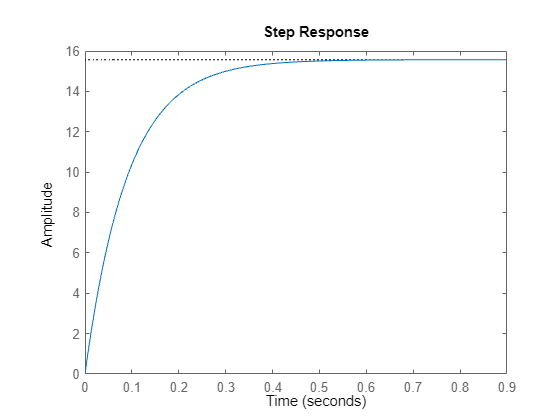

step(G_w_small)

fl = C_s*G_0_s

fl =
 
  85.63 s + 1713
  --------------
    s^2 + 11 s
 
Continuous-time transfer function.



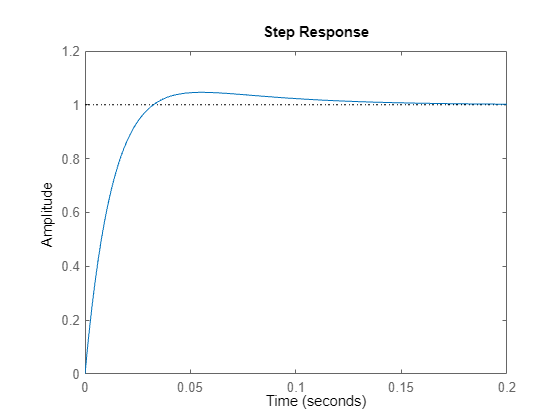

step(feedback(fl,1))

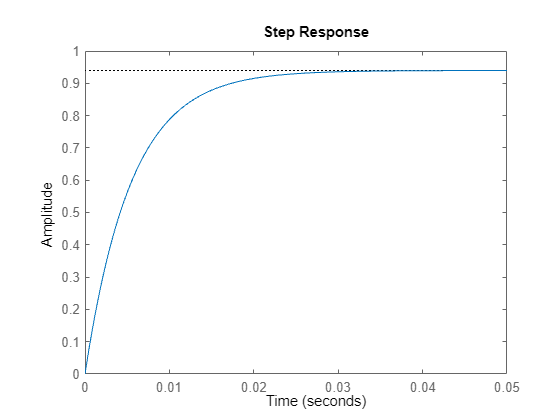

step(feedback(G_0_s, 1))


% Conversion to z domain
C_Z_tustin = c2d(C_s, t1, 'tustin')

C_Z_tustin =
 
  0.55 z - 0.45
  -------------
      z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



C_Z_tustin1 = c2d(C_s1, t1, 'tustin')

C_Z_tustin1 =
 
  0.95 z - 0.85
  -------------
      z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



G_Z = c2d(G_0_s,t1,'zoh')

G_Z =
 
    1.622
  ----------
  z - 0.8958
 
Sample time: 0.01 seconds
Discrete-time transfer function.




T_Z_tustin = C_Z_tustin * G_Z

T_Z_tustin =
 
     0.892 z - 0.7298
  ----------------------
  z^2 - 1.896 z + 0.8958
 
Sample time: 0.01 seconds
Discrete-time transfer function.



T_Z_tustin1 = C_Z_tustin1 * G_Z

T_Z_tustin1 =
 
     1.541 z - 1.379
  ----------------------
  z^2 - 1.896 z + 0.8958
 
Sample time: 0.01 seconds
Discrete-time transfer function.



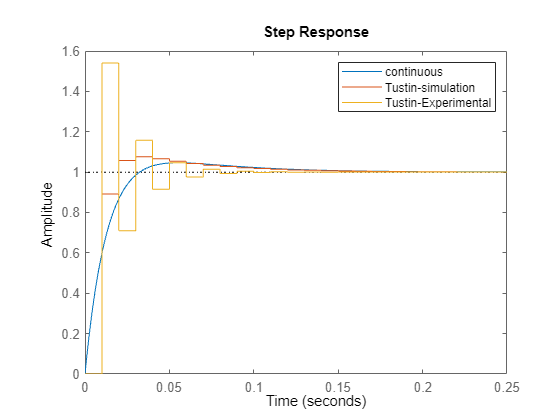


step(feedback(fl,1))
hold on
step(feedback(T_Z_tustin, 1))
step(feedback(T_Z_tustin1, 1))


legend('continuous', 'Tustin-simulation', 'Tustin-Experimental')